
fs=48000;
fc=16000;


mode='s7/';
fileFolder = fullfile(['receive/', mode]);
dirOutput = dir(fullfile(fileFolder,'*.pcm'));
fileNames = {dirOutput.name};
file_name = fileNames{end}

file_name = '20220325204116.pcm'


file=['receive/' , mode, file_name];
data= importdata(file);
data=data(1:end-40000)

data =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


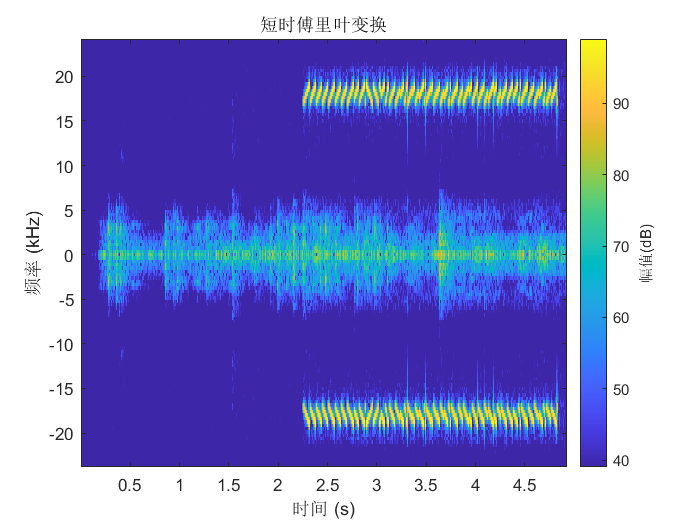

stft(data, fs)


time = length(data)

time = 236480

t = 0:1/fs:(time-1)/fs;

recv_sound_bf = BPassFilter(data, 18e3, 4e3, fs)

recv_sound_bf = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



%% 下变频  从高频信息提取低频信号(基带信号)
real_chirp_sound = recv_sound_bf.*cos(2*pi*fc*t)';
imag_chirp_sound = recv_sound_bf.*sin(-2*pi*fc*t)';
%% 低通滤波
real_cs = BPassFilter(real_chirp_sound, 3e3, 2e3, fs);
imag_cs = BPassFilter(imag_chirp_sound, 3e3, 2e3, fs);
rec_chirp_sound = real_cs + 1j*imag_cs;



A = movmean(abs(rec_chirp_sound), 1);
thresh = (max(A) - min(A))/3 + min(A);
inds = find(A > thresh)  % 找信号高于thresh的下标位置

inds =       108480
      108481
      108482
      108483
      108484
      108485
      108486
      108487
      108488
      108489


cut_rec_cs = rec_chirp_sound(inds(1):inds(end))  % 截取信号

cut_rec_cs = 	1.0e+03 *

  -0.4784 - 0.2989i
  -0.4254 - 0.3721i
  -0.3660 - 0.4379i
  -0.2923 - 0.4984i
  -0.2055 - 0.5413i
  -0.1180 - 0.5678i
  -0.0261 - 0.5853i
   0.0727 - 0.5845i
   0.1658 - 0.5636i
   0.2525 - 0.5334i


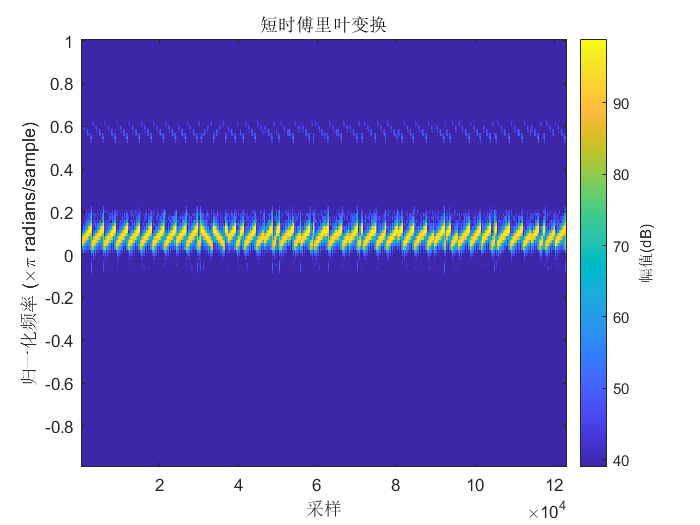


% +Nchirp

stft(cut_rec_cs)

fc = 16e3;           % 载波频率，主要用于纠正采样频偏（SFO），在发射端可忽略
sf = 7;              % 扩频因子
bw = 2e3;            % 带宽 2kHz
fs = 48e3;           % 采样率 48kHz
Nchirp = 2^sf/bw*fs; %一个Chirp的采样点数


phy = LoRaPHY(fc, sf, bw, fs);
phy.has_header = 0;         % explicit header 模式
phy.cr = 1;                 % code rate = 4/8 (1:4/5 2:4/6 3:4/7 4:4/8)
phy.crc = 0;                % 允许 payload CRC
phy.preamble_len = 8;       % 前导码： 8 basic upchirps

% 解调
[symbols_d, cfo] = phy.demodulate(cut_rec_cs);
fprintf("[demodulate] symbols:\n");

[demodulate] symbols:


disp(symbols_d);

    45
    85
    85
    41
    93
    73
    25
   113




% 解码
[data, checksum] = phy.decode(symbols_d);
fprintf("[decode] data:\n");

[decode] data:


disp(data);
fprintf("[decode] checksum:\n");

[decode] checksum:


disp(checksum);




function y = BPassFilter(data, centerFre, offsetFre, sampFre)
    % 设计I型带通滤波器
    M = 0 ;    % 滤波器阶数（必须是偶数）
    Ap = 0.82; % 通带衰减
    As = 45;   % 阻带衰减
    Wp1 = 2*pi*(centerFre - offsetFre)/sampFre;  % 算出下边频
    Wp2 = 2*pi*(centerFre + offsetFre)/sampFre;  % 算出上边频

    % 矩形窗
    N = ceil(3.6*sampFre/offsetFre); % 计算滤波器阶数,采用矩形窗，3dB截频在中心频率到上下边频的中点
    M = N - 1;
    M = mod(M,2) + M ; % 使滤波器为I型(偶数)

    % 单位脉冲响应的下脚标
    h = zeros(1,M+1);  % 单位冲击响应变量赋初值
    for k = 1:(M+1)
        if (( k -1 - 0.5*M)==0)
            h(k) = Wp2/pi - Wp1/pi;
        else
            h(k) = Wp2*sin(Wp2.*(k - 1 - 0.5*M))/(pi*(Wp2*(k -1 - 0.5*M))) - Wp1*sin(Wp1*(k - 1 - 0.5*M))/(pi*(Wp1*(k -1 - 0.5*M)));
        end
    end
    y = filter(h,1,data);
end
